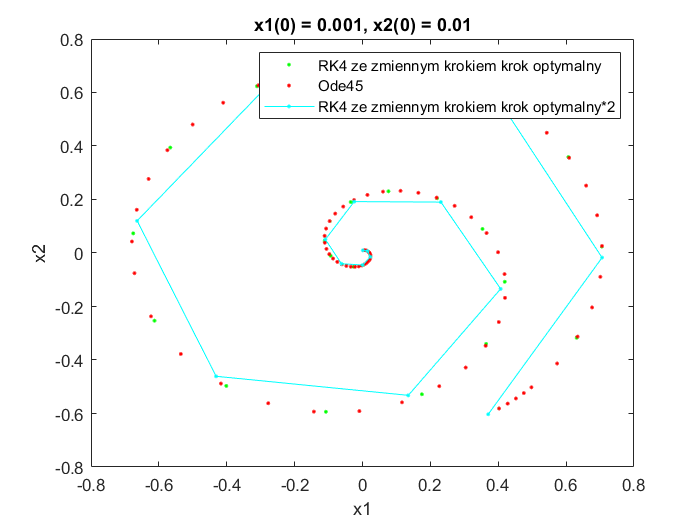

initial_cond = [8,8 ; 0,0.5 ; 10,0 ; 0.001,0.01; 0,-0.1];
example = 4;
krok_rk4 = 0.1;
krok = 0.5;
krok_rk4_zmien = 0.01;

fun = @(t,x) [x(2) + x(1)*(0.5 - x(1).^2 - x(2).^2); -x(1) + x(2)*(0.5 - x(1).^2 - x(2).^2)];

%[data_rk4, iters_rk4] = RK4(krok_rk4, initial_cond(example,:));
%[data_pc, iters_pc] = predictor_corrector(krok, initial_cond(example,:));
[data_rk4_zmien, iters_rk4] = RK4_zmien(krok, initial_cond(example,:));
[t, data_ode] = ode45(fun, [0, 15], initial_cond(example,:));

[data_big_step, iters] = RK4_zmien(krok*2, initial_cond(example,:));

plot(data_rk4_zmien(:,1), data_rk4_zmien(:,2), '.g');
hold on
title('x1(0) = 0.001, x2(0) = 0.01');
xlabel('x1');
ylabel('x2');
plot(data_ode(:,1), data_ode(:,2), '.red');
plot(data_big_step(:,1), data_big_step(:,2), '.-cyan');
legend('RK4 ze zmiennym krokiem krok optymalny', 'Ode45', 'RK4 ze zmiennym krokiem krok optymalny*2');
hold off